clear
clc

format long  %Large no of float points are used to reduce the trucation error.
N = 5;  % No. of nodes  - Can be changed

L = 0.2;  % Thickness of plane slab
delta_x = L/(N-1)   % Element size

delta_x =    0.050000000000000


x = 0:delta_x:L;    % Nodes positions 
k_const = 18;
alpha = 0.000228;    % Thermal diffusivity 
h = 45;           % Heat transfer conefficent of air  
T_inf = 303;     % Air temperature

TimeStep_limit = (k_const*(delta_x^2))/(2*alpha*(h*delta_x + k_const)) %stability criteria

TimeStep_limit =    4.873294346978558


TimeStep = 0.01*TimeStep_limit   %timestep taken

TimeStep =    0.048732943469786


tau = (alpha*TimeStep)/(delta_x^2); % Fourier number  or non dimenstional time

TimeofInterest = 2; % in minutes - can be changed 
iterationRequired = round((TimeofInterest*60)/TimeStep) % no of iterations

iterationRequired =         2462


**Analytical solution **

x_analytical = linspace(0,.2,20);  % position long slab thickness
T_analytical = 373 - (116.67*x_analytical); % exact temperatures at these positions


***a. Numerical Solution***: 

**Governing Differential equation: **$\frac{\partial^2 }{\partial x^2 }T=\alpha^{-1} *\frac{\partial }{\partial t}T$

**Discritizing the equation for algebric equations: using explicit method**

- **for first node = **$T_1 =373K$ (by temperature boundary condition )

- **for inner nodes = **$T_n^{i+1} =\tau *\left(T_{n+1}^i +T_{n-1}^i \right)+\left(1-2*\tau \right)*T_n^i$

- **for last node= **$T_N^{i+1} =T_N^i *\left(1-2*\tau -2*\tau *h*\Delta x/k\right)+2*\tau *h*\Delta x*\frac{T_{\infty } }{k}+2*\tau *T_{n-1}^i$

**Stability criteria: **$\left(1-2*\tau -2*\tau *h*\Delta x/k\;\right)\ge 0\;$

**from above formula we get maximum timestep that can be taken to avoid oscillation of solution**

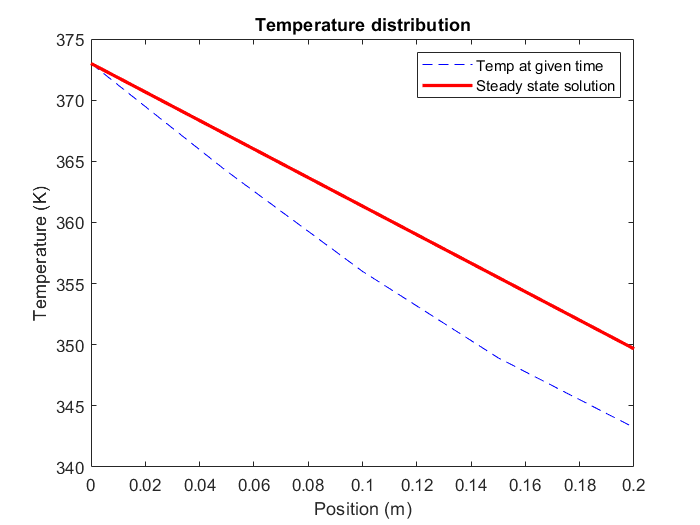

T_0(1:N) = 303; % Initial conditi
i=0;

[T_next_i, i] = NumericalMethod(T_0,N,tau,h,delta_x,k_const,T_inf,i,TimeStep);

while i<= iterationRequired
    TimeStep = (i+1)*TimeStep;
    [T_next_i, i] = NumericalMethod(T_next_i,N,tau,h,delta_x,k_const,T_inf,i,TimeStep);
    if T_next_i(N) == 349
        SteadyStateTime = i*TimeStep;
       
        break
    end
    
end

plot(x,T_next_i, 'b--')
hold on
plot(x_analytical,T_analytical,"r","LineWidth",2)
xlabel('Position (m)')
ylabel("Temperature (K)")
title("Temperature distribution")
legend("Temp at given time","Steady state solution")
hold off

function [T_next_i, i] = NumericalMethod(T_i,N,tau,h,delta_x,k_const,T_inf,i,TimeStep)
    T_next_i(1)=373;
    for n = 2:N
        if n < N
            T_next_i(n) = tau*(T_i(n+1)+T_i(n-1)) + (1-2*tau)*T_i(n);
        elseif n==N
            T_next_i(n) = T_i(n)*(1-2*tau-(2*tau*h*delta_x/k_const)) + 2*tau*T_i(n-1) + (2*tau*h*delta_x*T_inf/k_const);
        end
    end
    i = i+1;
    
end